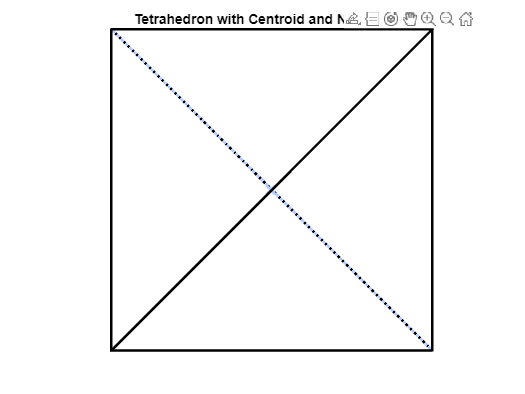

clear
% Define the vertices of a tetrahedron
V = [
    1 1 1;    % Vertex 1
    -1 -1 1;  % Vertex 2
    -1 1 -1;  % Vertex 3
    1 -1 -1;  % Vertex 4
];

% Define the faces of the tetrahedron
F = [
    1 2 3;  % Face 1
    1 2 4;  % Face 2
    1 3 4;  % Face 3
    2 3 4;  % Face 4
];

% Calculate the centroid of the tetrahedron
centroid = mean(V, 1);

% Plot the original tetrahedron
figure;
hold on;
patch('Faces', F, 'Vertices', V, 'FaceColor', 'none', 'EdgeColor', 'k', 'LineWidth', 2);

% Plot the centroid
scatter3(centroid(1), centroid(2), centroid(3), 100, 'Marker', 'x', 'MarkerEdgeColor', [0.7 0.8 1], 'LineWidth', 2);

% Add edges from the centroid to all the vertices
for i = 1:size(V, 1)
    plot3([centroid(1), V(i, 1)], [centroid(2), V(i, 2)], [centroid(3), V(i, 3)], 'Color', [0.7 0.8 1], 'LineWidth', 2, 'LineStyle', ':');
end

% Set plot attributes
axis equal;
axis off; % Remove the axes
title('Tetrahedron with Centroid and New Edges');
grid on;
hold off;